tNIR =array2table(NIR);

err = [];
for i = 1 : 10
    c = cvpartition(60,'KFold',10);
    [XL,YL,XS,YS,BETA,PCTVAR,MSE,stats] = plsregress(NIR,octane,i, 'cv',10,'mcreps',5);
    err =[err stats.Yresiduals];
    MSE
end

MSE =     0.0621    0.0186
    2.3984    1.7374


MSE =     0.0618    0.0188    0.0147
    2.3957    1.8195    0.1550


MSE =     0.0622    0.0187    0.0146    0.0095
    2.3797    1.7594    0.1520    0.0655


MSE =     0.0620    0.0189    0.0147    0.0104    0.0035
    2.3974    1.7934    0.1514    0.0673    0.0596


MSE =     0.0615    0.0187    0.0145    0.0096    0.0036    0.0030
    2.3831    1.8017    0.1538    0.0679    0.0605    0.0597


MSE =     0.0620    0.0186    0.0145    0.0095    0.0036    0.0030    0.0024
    2.3831    1.8012    0.1563    0.0679    0.0587    0.0586    0.0522


MSE =     0.0621    0.0186    0.0145    0.0100    0.0038    0.0030    0.0025    0.0021
    2.3719    1.7806    0.1545    0.0678    0.0592    0.0596    0.0545    0.0540


MSE =     0.0615    0.0185    0.0143    0.0098    0.0035    0.0030    0.0025    0.0021    0.0018
    2.3775    1.7515    0.1476    0.0674    0.0603    0.0596    0.0531    0.0504    0.0529


MSE =     0.0619    0.0190    0.0146    0.0100    0.0037    0.0029    0.0025    0.0021    0.0017    0.0015
    2.4423    1.9501    0.1691    0.0661    0.0607    0.0612    0.0535    0.0507    0.0552    0.0595


MSE =     0.0619    0.0188    0.0146    0.0101    0.0039    0.0029    0.0025    0.0021    0.0017    0.0016    0.0014
    2.4067    1.7864    0.1559    0.0645    0.0586    0.0612    0.0544    0.0504    0.0532    0.0567    0.0613


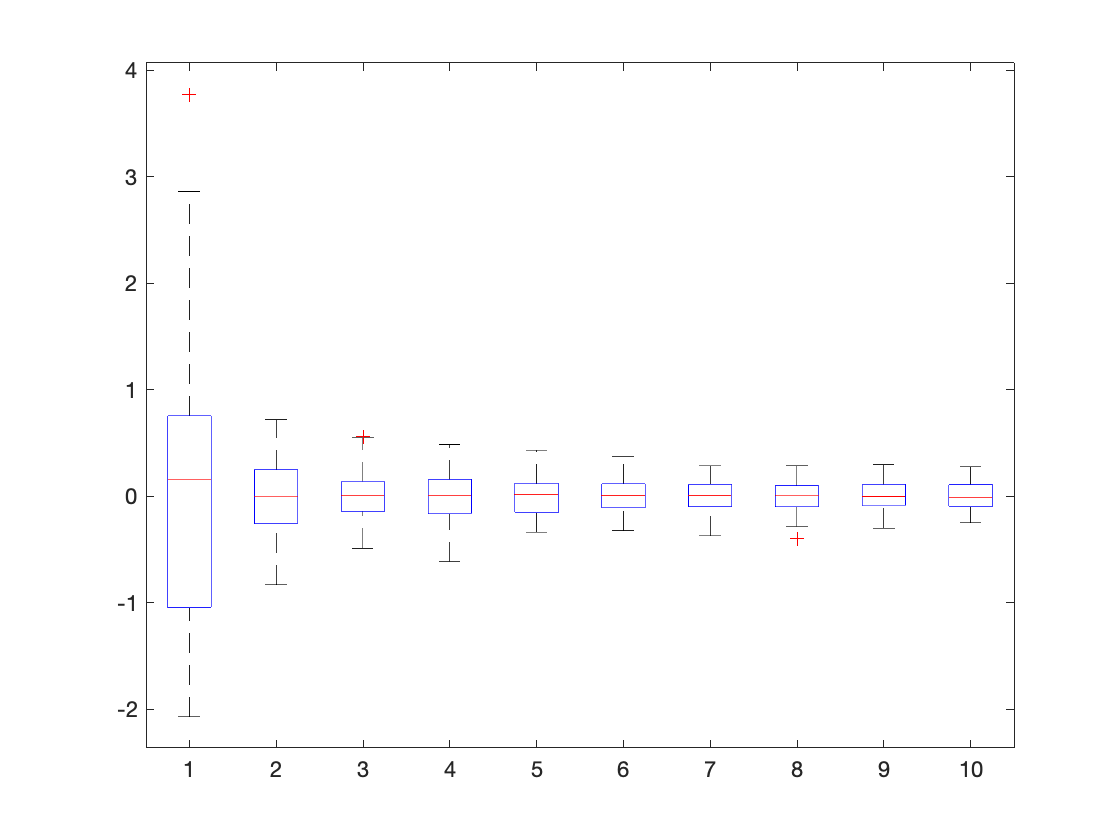


boxplot(err)

num = linspace(1, 63, 5)

num =     1.0000   16.5000   32.0000   47.5000   63.0000


numstr = num2str(num)

numstr = '1         16.5           32         47.5           63'

tests = str2cell(numstr)

tests = 5×1 cell 数组
    {'1'   }
    {'16.5'}
    {'32'  }
    {'47.5'}
    {'63'  }


testR = [sp.PerformanceSta.RMSECV(:,1),sp.PerformanceSta2.RMSECV(:,1)]

testR =     0.2943    0.2647
    0.2642    0.2916
    0.2754    0.2993
    0.2448    0.2681
    0.2964    0.2694
    0.2607    0.2768
    0.2667    0.2873
    0.2509    0.2570
    0.3527    0.2658
    0.2468    0.2712


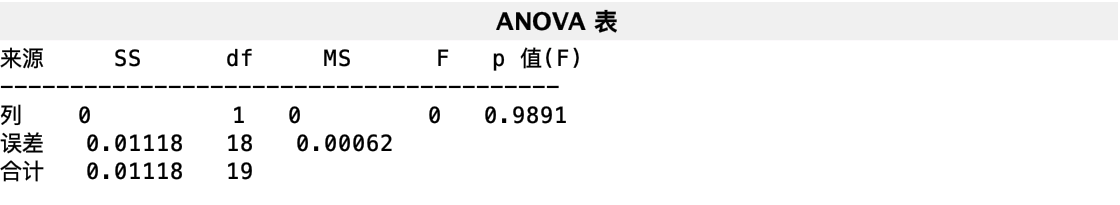

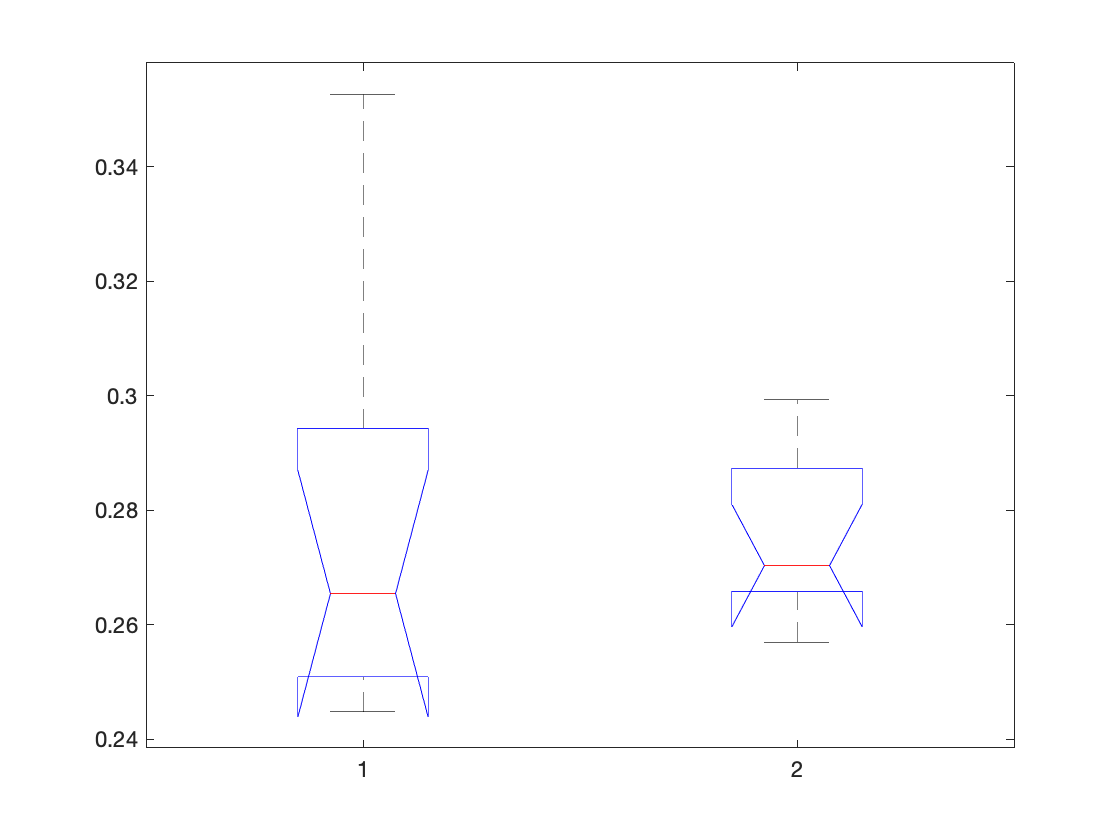

p = 0.9891

p = anova1(testR)